# Background and Introduction to ASMITA

**A**ggregated **S**cale **M**orphological **I**nteraction between **T**idal basin and **A**djacent coast

The ASMITA model is used to examine long-term morphological change in tidal inlets and estuaries.

## Getting Started

This is a Matlab™ LiveScript, written as a series of Sections which can be run sequentially using the '*Run Section*' option on the LIVE EDITOR tab. The output from the scripts can be displayed in a column to the right of the script, or inline, by changing the '*VIEW'* option on the VIEW tab.

## Background to ASMITA

The idea behind ASMITA is that a tidal basin, or estuary can be sub-dividing into a number of elements (Figure 1).  Each element has an equilibrium condition when unperturbed and following some form of perturbation (eg. sea level rise, addition or removal of volume or area) the model seeks a new equilibrium.  For example, if under initial conditions the accommodation space is zero (no net change in the transport of sediment), with increased mean sea level the accommodation space becomes positive and sediment may be imported, the opposite is true when sea level falls.

 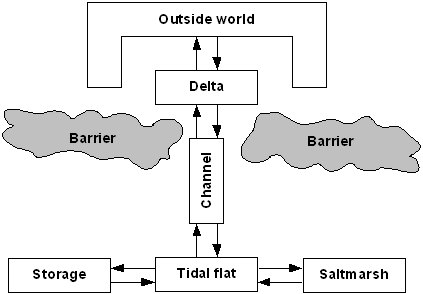                                                   

*Figure **1** - Schematisation of an estuary or inlet into a number of elements as used in ASMITA*

The key concepts of the ASMITA model are:

- The estuary is schematized into a number of geomorphologic elements;

- The state of each element is described by its volume and plan area (water or sediment);

- Integrated parameters of hydrodynamics (tidal prism, or tidal range) are used;

- Empirical relationships define the morphological equilibrium for each element;

- Deviation from the morphological equilibrium causes sediment demand; and

- A gradient in sediment demand drives sediment transport, and thereby morphological change.

 The theoretical background to the model is explained in various published papers as detailed in the Bibliography.

## Single element model

### Sediment exchange

The single element assumes a constant plan area, such that the sediment in/out due to horizontal exchanges with the outside world and the erosion/deposition at the bed due to vertical exchanges determine the change in volume of the element. The calculation can be done in terms of sediment volume or water volume. 

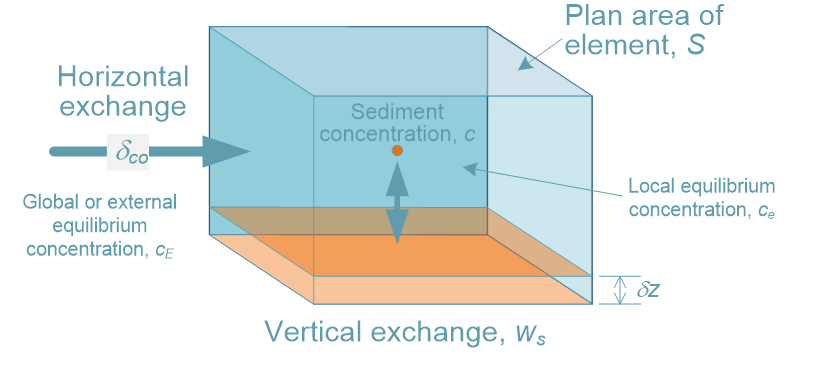

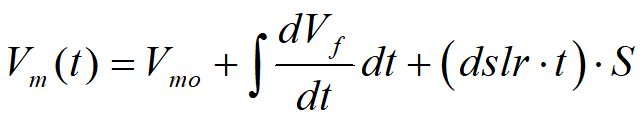  Total volume at time t, including variations in water level

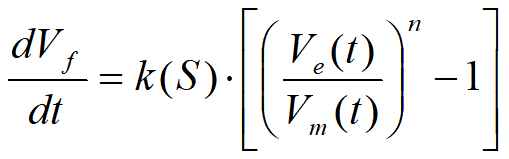                    Rate of volume change relative to a fixed surface

                         Equilibrium volume based on relationship with tidal prism

% Input parameters
Vm0 = 1.3e9;                 %initial volume of element (m^3)
S  = 2.7e8;                  %plan area of element (m^2)
dslr = 0.004;                %rate of sea level rise (m/yr)
a = 1.2;                     %tidal amplitude:
dt = 1;                      %time step (yr)
n = 5;                       %sediment transport coefficient (-)
w = 0.002;                   %vertical exchange rate (m/s)
d = 20000;                   %horizontal exchange rate (m/s)
cE = 0.02;                   %equilbrium concentration (-)
y2s = 365.25*24*3600;        %conversion from years to seconds

% Derived parameters
P = 2*a*S;                   %initial tidal prism (m^3)
alpha = Vm0/P;               %assume that the initial system is in equilibrium (-)
dP = S*dslr*dt;              %change in tidal prism over time step dt (m^3)

% Compute volume change in one year
k = (w*cE*S)/(d+w*S);        %constant term in dV/dt
Ve = alpha*(P+dP);           %equilibirum volumen (m^3)
Vm = Vm0;                    %initialise the element volume (m^3)
dVf = k*((Ve/Vm)^n-1)*dt*y2s;%sediment flux in a time step (m^3)
Vm = Vm+dVf+dP;              %updated water volume of element (m^3)

% Display results
fprintf('Sediment flux = %g m^3 in a year\n',dVf)

Sediment flux = 5088.69 m^3 in a year


fprintf('Change in water volume = %g m^3 in a year\n', Vm-Vm0)

Change in water volume = 1.08509e+06 m^3 in a year


To examine the change over time one needs to carry out the above calculation for a number of time steps. Your are now going to write some code to calculate and plot the change in sediment and water volumes over 100 years.

You need to write a script to intialise the inputs and a function to carry out the computation. The function can use the blank *sediment_flux.m* file provided. Start by considering:

- What is needed in the calling script to (a) be able to call the function; and (b) plot the results

- What input variables does the function need?

- What output variables need to be returned by the function call?

- How should the time-step be determined?

- Can the code be vectorised (much quicker), or is a 'for' loop needed?

An important aspect of writing code is documentation. It may seem a distraction when you first write code but it pays dividends as you do more. By having a clear definition of the inputs and outputs to functions it becomes much easier to re-use code. and to quickly check what a function does. If you type *help <function_name> *for some function in the `Command Window`, the help text from the function will be displayed. For example, for the, as yet unwritten, *sediment_flux *function*,* the help looks like this:

help sediment_flux

 
 -------function help------------------------------------------------------
  NAME
    sediment_flux.m
  PURPOSE
    compute the sediment flux in/out of a single element model
  USAGE
    [outputArg1,outputArg2] = sediment_flux(inputArg1,inputArg2)
  INPUT
    inputArg1 - ????                       %edit to define inputs 
    inputArg2 - ????
  OUTPUT
    outputArg2 - ????                      %edit to define outputs
    outputArg2 - ????
  SEE ALSO
    Asmita App
  NOTE
    ??? notes to help user understand how to use the function ????
 
  Author: ????
  University of Southampton (c)Apr 2023
 --------------------------------------------------------------------------



Hopefully it will be a bit more informative once you have completed writing your function. 

As well as the help documentation, in-line documentation is also important and makes clear what shorthand variable names actually mean and helps to explain what the code is doing (e.g. see script above). This proves useful over time because if you come back to some work after a few months or years, it makes it much easier to work out what the function does. It also makes it easier to pass the function to someone else. I usually start coding a function by writing the help, even though I invariably edit the help text as the function evolves. The benefit of working this way is that by writing down what the function does, defining the inputs and outputs, and thinking about what else a user might need to know, clarifies my thinking about the best way to code the function. 

To illustrate the type of output you should get based on the parameter settings above and using a function in the Asmita App run the following:

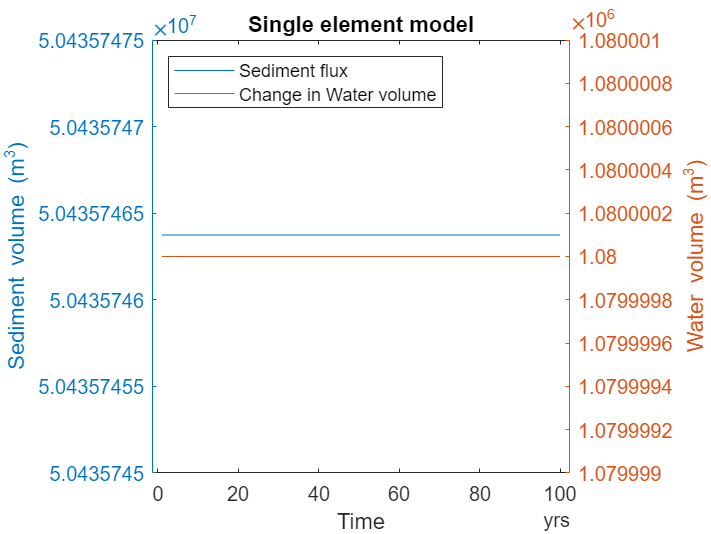

accel = ones(1,100);         %factor to accelerate rate of slr, 1 is a linear rate of rise
sedflux_script         

With a linear rate of slr the result is a bit boring. Make the rate of sea level rise accelerate exponentially:

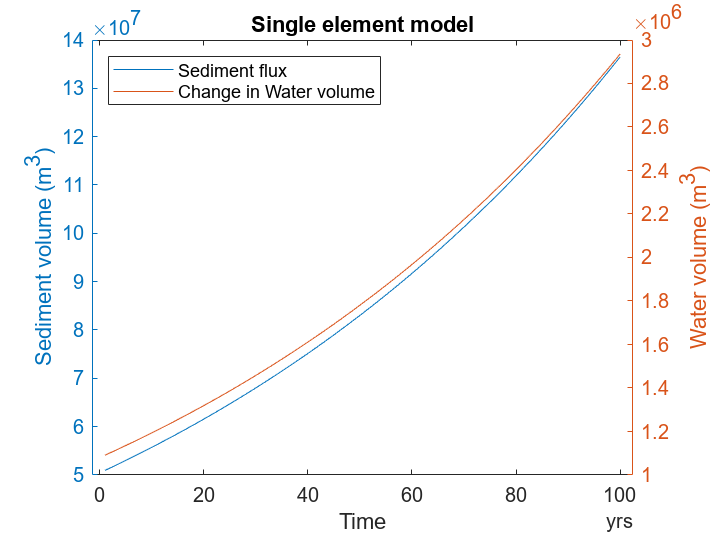

accel = exp((1:100)/100);   %factor to accelerate rate of slr with an exponential rate of rise
sedflux_script 

### Sea level rise

Linearising around equilibrium, Kragtwijk et al (2004) show the morphological time scale to be: 

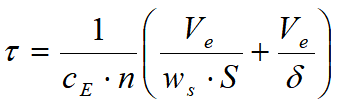

As we have already defined the parameters need above we can estimate the morphological time scale for our single element as follows:

tau = 1/(cE*n)*(Ve/(w*S)+Ve/d);
fprintf('Morphological time scale %g yr\n',tau/y2s)

Morphological time scale 0.0213957 yr


Using the same concept we can determine the limiting rate of sea level rise that a system can cope with before it simply drowns:

       

max_dslr = w*d*cE/(d+w*S);   %the variable dslr is used above, so choose a different name
fprintf('Limiting rate of slr %g m/yr\n',max_dslr)

Limiting rate of slr 1.42857e-06 m/yr


Are these results what you would expect given the formulation set out above?

### Parameter sensitivity

The above equations are sufficient to explore the influence of varying the input parameters, namely:  *w, d, cE *and* S*. 

clearvars                    %clear previous variable assignments

Start by setting up some ranges for each of the governing parameters

logint = logspace(0,2,7);    %log spaced intervals
w = 1e-5*logint;             %vertical exchange
d = 100*logint;              %horizontal exchange
cE = 1e-6*logint;            %global equilbrium concentration
S = 1e6*logint;              %surface area of element
s2y = 3600*24*365;           %seconds to years convertion factor
response = @(w,d,c,S) (w*d*c)./(d+w*S)*s2y*1000;  %anonymous function for response

By specifying values for each parameter between 1 and 7 the rate of sea level rise is then given by:

dslr = response(w(2),d(3),cE(4),S(6));
fprintf('Limiting rate of slr %g m/yr\n',dslr)

Limiting rate of slr 2.15386 m/yr


Now let's produce some plots to show the parameters vary against each other. Since there are four variables we need to keep twoof these constant, in order to create a suface plot of the rate of sea level rise for the other two variables.

Select the variables to be held constant in a plot of vertical exchange, w, against  horizontal exchange, d:

nc=1; cE(nc)   %equilibrium concentration, cE

ans = 1.0000e-06

ns=7; S(ns)    %plan area, S

ans = 100000000

Code for plot

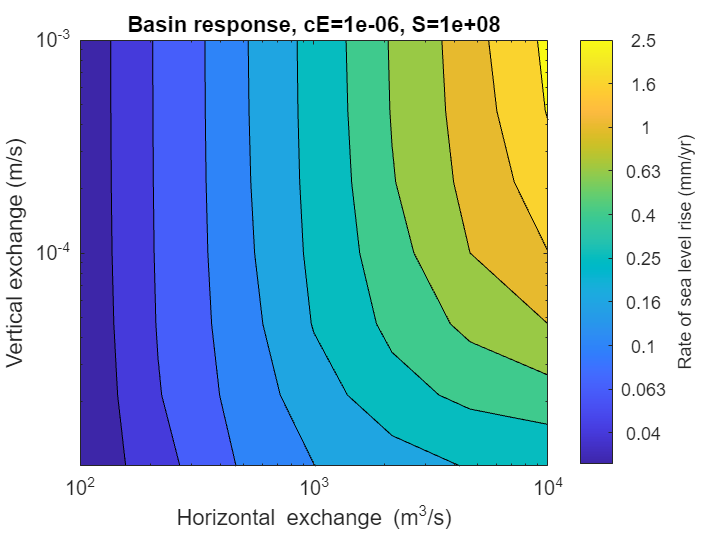

figure('Name','DSLR_w_d');
ax1 = axes;
dslr1 = response(w',d,cE(nc),S(ns));                 %calculate surface
contourf(ax1,d,w',log10(dslr1))                      %plot surface
ax1.XAxis.Scale = 'log';                             %add log axes
ax1.YAxis.Scale = 'log';
hc1 = colorbar;                                      %add colorbar
hc1.Label.String = 'Rate of sea level rise (mm/yr)';
hcticks = hc1.Ticks;
hc1.TickLabels = num2str(10.^(hcticks)','%0.2g');
xlabel('Horizontal exchange (m^3/s)');               %add axis labels  and title
ylabel('Vertical exchange (m/s)');
title(sprintf('Basin response, cE=%0.3g, S=%0.3g',cE(nc),S(ns)))

Select the variables to be held constant in a plot of concentration, cE, against plan area, S:

nw=1; w(nw)    %vertical exchange, w

ans = 1.0000e-05

nd=1; d(nd)    %horizontal exchange, d

ans = 100

Code for plot

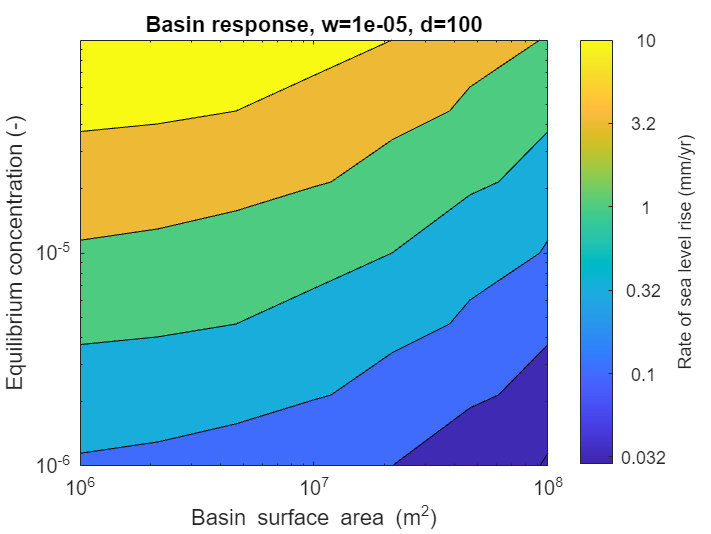

figure('Name','DSLR_cE_S');
ax2 = axes;
dslr2 = response(w(nw),d(nd),cE',S);                 %calculate surface
contourf(ax2,S,cE',log10(dslr2))                     %plot surface
ax2.XAxis.Scale = 'log';                             %add log axes
ax2.YAxis.Scale = 'log';
hc2 = colorbar;                                      %add colorbar
hc2.Label.String = 'Rate of sea level rise (mm/yr)';
hcticks = hc2.Ticks;
hc2.TickLabels = num2str(10.^(hcticks)','%0.2g');
xlabel('Basin surface area (m^2)');                  %add axis labels  and title
ylabel('Equilibrium concentration (-)');
title(sprintf('Basin response, w=%0.3g, d=%0.0f',w(nw),d(nd)))

#### Setting dynamic input parameters

When setting up the model some of the parameters need to be estimated based on the dimensions and tidal properties of the estuary or inlet. The basis for defining the parameters is explained in the Asmita manual and the supporting papers, which you can access from the `Help` menu, once you have loaded the App. 

In this practical you will set-up a model for the Humber Estuary. This needs information about the estuary dimensions and conditions such as tide and river properties. When doing this for yourself, this would require some data collation to find the source data and then some mapping, or GIS work, to establish things like plan areas and volumes. If a description, or conceptual model, of the estuary is available, this can help developing the model schematisation. For further background on how to develop a conceptual model see the [Art of Modelling](matlab:open('./The_art_of_modelling_v3.pdf')) paper. Some discussion of schematisation is provided in [Rossington et al., 2011](https://doi.org/10.1016/j.margeo.2011.01.005), and the background to defining the model parameters, *w, d, and cE *is given in [Wang* et al, *2008](https://doi.org/10.1201/noe0415453639-c14).

Vertical exachange (based on settling velcity for the typical sediment grain size)

d50 = 0.0001;                                        %sediment grain size (m)
rhow = 1025;                                         %density of water (kg/m3)
rhos = 2650;                                         %density of sediment (kg/m3)
visc = 1.36e-6;                                      %kinematic viscosity (m2/s)
rhoc = 0.72;                                         %suspended sediment density (kg/m3)
%following function for settling velocity is in CoastalTools and Asmita Apps:
ws = settling_velocity(d50,9.81,rhow,rhos,visc,rhoc);
fprintf('settling velocity %0.2g m/s\n',ws)

settling velocity 0.0056 m/s


Horizontal exchange

Vol = 1.08e9;                                        %element volume (m3)
Area = 1.87e8;                                       %element plan area (m2)
vel = 1.5;                                           %peak flow in element (m/s)
Tp = 12.4*3600;                                      %tidal period (s)
CSA = 7.5e4;                                         %cross-section area at mouth (m2)

%Dependent properties
Hydepth = Vol/Area;                                  %hydraulic depth of element
D = vel^2*Hydepth/ws;                                %horizontal advection
Lx = vel*Tp/pi;                                      %tidal excursion length
delta = D*CSA/Lx;                                    %horizontal exchange
fprintf('horizontal exchange %.0f m/s\n',delta)

horizontal exchange 8094 m/s


The global equilibrium concentration, cE, is used as a calibration parameter (see [Wang* et al, *2008](https://doi.org/10.1201/noe0415453639-c14)).

There is an Excel spreadsheet that tabulates the dimensions of the estuary and can be used to perform these calculations.

## Asmita App

Asmita is a Matlab™ App to examine the long-term morphological response of tidal inlets and estuaries. Rather than modelling the flows and sediment transport in detail, the model considers the sediment exchange between morphological elements (channel, tidal flat, etc) and the determines the exchanges needed based on the forcing conditions and a specified set of equilibrium conditions for each type of element. The model output provides the change in element volume over time and can also examine changes in tidal prism, biomass production (if saltmarshes are included) 

How to use Asmita is explained in the Asmita manual, along with details of the models used, Guidance is also available in the online Help (see Asmita in the Matlab Supplemantray Tools Documentation).

### Installing the Asmita App

Asmitais installed as an App and requires muitoolbox and dstoolbox to be installed. The download for each of these includes the code, documentation and example files. The files required are: 

- dstoolbox.mltbx

- muitoolbox.mltbx

- Asmita.mlappinstall

#### Installing the Toolboxes

You can check whether the required toolboxes are already installed using:

addons = matlab.addons.installedAddons

addons = 14×4 table
                Name                 Version    Enabled                  Identifier              
    _____________________________    _______    _______    ______________________________________

    "ModelSkill"                     "2.10"      true      "a9c4ee73-0fd4-450f-97e3-52f77de998c5"
    "ChannelForm"                    "3.10"      true      "05bbb74d-cb4f-4185-80d5-5f7cd53c2022"
    "SedTools"                       "1.01"      true      "be75f07c-b943-4104-a732-fe771a77f928"
    "CSTmodel"                       "2.04"      true      "35f85c95-efcd-4958-a6f9-4b7e902b8080"
    "Mapping Toolbox"                "5.4"       true      "MG"                                  
    "Global Optimization Toolbox"    "4.8"       true      "GD"                                  
    "Asmita"                         "3.1"       true      

%which displays the installation details in the command window (you may
%need to scroll the table to see both toolboxes)

If not already installed, the two toolboxes can be installed using the `Add-Ons>Manage Add-Ons` option on the` HOME` tab of Matlab™. Alternatively, right-click the mouse on the ‘*mltbx*’ files and select I`nstall`. All the folder paths are initialised upon installation and the location of the code is also handled by Matlab™. The location of the code can be accessed using the options in the `Manage Add-Ons` UI.

%uncommenting the following lines of code will install the toolboxes
% matlab.addons.install('dstoolbox.mltbx',true)
% matlab.addons.install('muitoolbox.mltbx',true)

%once tooolboxes are installed, comment these two lines out again

If you run the installedAddons function again you should now see the toolboxes listed.

#### Installing the App

The App is installed using the `Install Apps` button on the `APPS `tab in Matlab™. Alternatively, right-click the mouse on the ‘*mlappinstall*’ file and select I`nstall`. Again all the folder paths are initialised upon installation and the location of the code is handled by Matlab™.

Once installed, the App can be run from the `APPS` tab. This sets the App environment paths, after which the App can be run from the *Command Window* using:

>>  Asmita;

The App environment paths can be saved using the `Set Path` option on the Matlab™ `HOME` tab.

Documentation can be viewed from the Supplementary Software in the Matlab™ Documentation. The location of the code can be accessed by hovering over the App icon and then finding the link in the pop-up window.

%uncommenting the following lines of code will install the Asmita App
% appinfo = matlab.apputil.install('Asmita.mlappinstall')     
%which displays the installation details in the command window

%once App is installed, comment the above line out again

%to check what Apps are installed, use:
% appinfo = matlab.apputil.getInstalledAppInfo

### Running Asmita

A graphical user interface (UI) is used to load data, run models, manipulate the data, carry out some simple statistical procedures, plot results and export model output.

If you installed Asmita as an App use the icon on the `APPS` tab, or if the App environment paths have been set, simply type Asmita at the command prompt:

>> Asmita;   *OR*     >>ct = Asmita; if you want a handle to the model instance.

A splash screen crediting the developers appears for a few seconds before being replaced by the Asmita interface. Documentation can be viewed from App `Help` menu, or the Supplemental Software in the Matlab™ Documentation. If the App environment paths have been set, you can also type Asmita in the Search Documentation window (top right corner of the Matlab™ UI).

The location of the code can be accessed by hovering over the App icon in the `APPS` tab and then finding the link in the pop-up window.

### Using Asmita

To get familiar with the use of Asmita, we will setup a model for the Humber estuary. The instructions below are also available as slides showing the various screens used to input data, etc, see: '[ASMITA Humber practical.pdf](matlab:open('./ASMITA Humber practical.pdf'))'. You will also need the 'Humber 3EM model parameters.xlsx' spreadsheet and the 'Humber 3EM element parameters.txt text file containing the [element properties](matlab:open('./Humber 3EM element parameters.txt')). 

#### Setup Estuary parameters

Most the model parameters needed are provided in the spreadsheet. These need to be entered using the various setup UIs provide in the App.

        `Setup > Estuary > System Parameters`

which should appear as shown below.

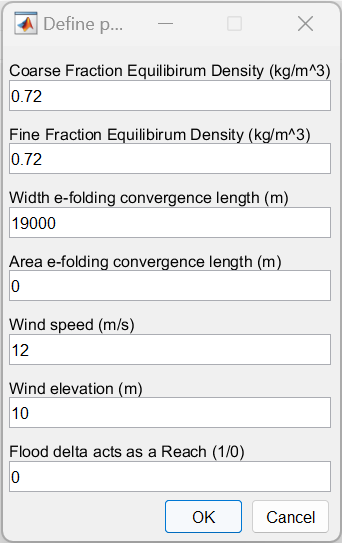

        `Setup > Estuary > Water Levels  `is similar. 

### Setup Element parameters

Then it is best to define the elements that are going to be used. 

        `Setup > Elements > Define Elements`

 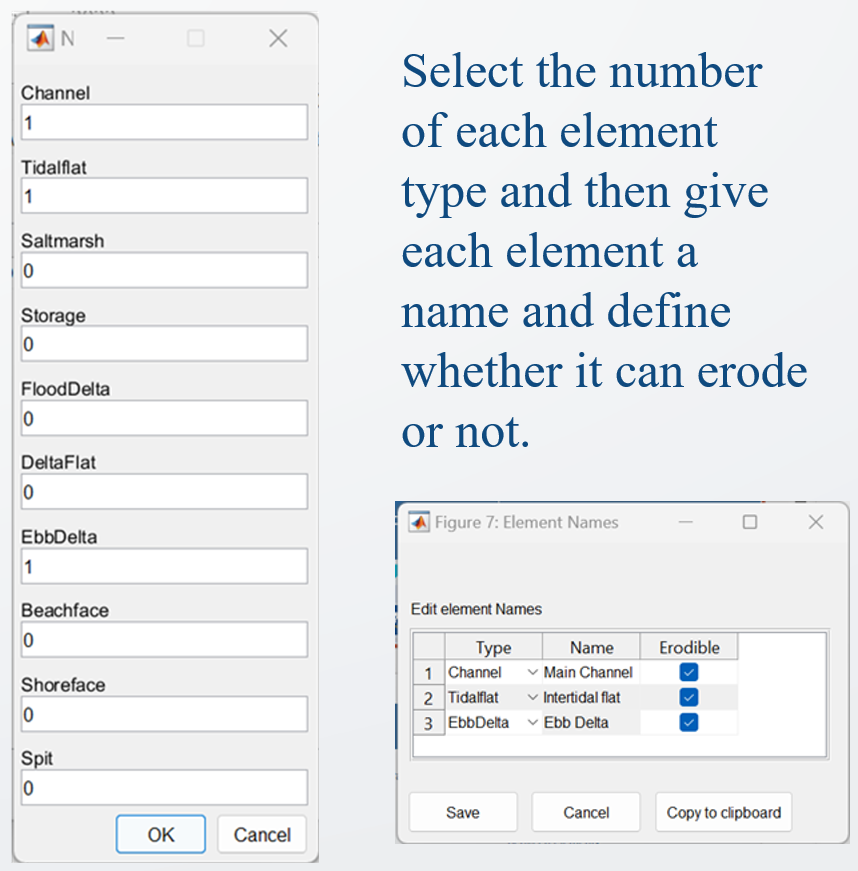

Now load the element properties using the 'Humber 3EM element parameters.txt text file provided. Note: the data in the file must be in the order of the define elements. As shown in the above image, this is 1=Channel; 2=Tidal Flat and 3= ebb Delta.

You can also define the elements manually, by selecting each element and populating the element parameters based on the values given in the spreadsheet. 

`Setup > Elements > Load Parameters`

Now define the horizontal exchanges between the element. If you have drawn a sketch based on the values in the spreadsheet, this will help you setup the dispersion matrix:

        `Setup > Estuary > Dispersion`

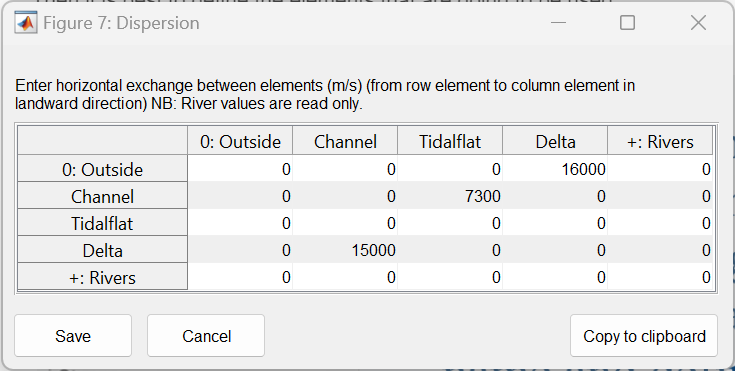

Define the exchanges proceeding upstream, which in the case illustrated above, goes from the Outside to the Delta (1st row- 4th column), via the Delta to the Channel (4th row-2nd column) and finally from the Channel to the Tidalflat (2nd row-3rd column). The resulting network can be viewed ont the Tides>Network tab.

**If you have not already done so, it is a good idea to ****save**** the model at this point so that if you make a mistake, you do not have to go all the way back to the beginning.**

### **Setup River Input**

The first step is define which element the river flows into (the Channel element in this example).

        `Setup > Rivers > River Inputs`

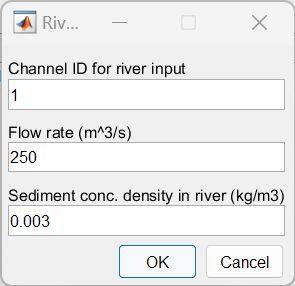

Then the flow path needs to be defined. This is similar to the definition of the disperion but in the opposite direction, proceeding from the river to the sea. 

        `Setup > Rivers > River Advection`

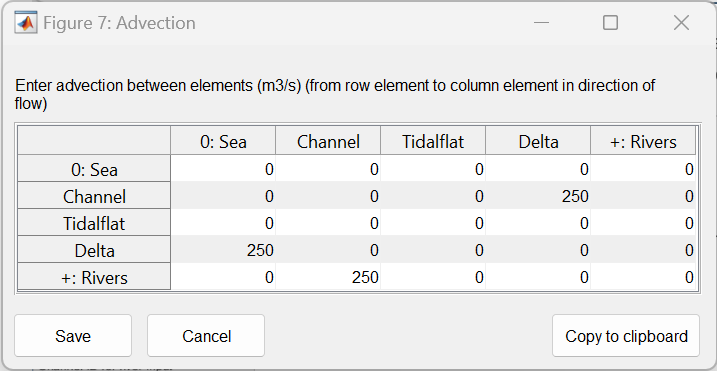

The resulting flowpath network can be viewed ont the Flows>Rivers tab.

### Setup Run Parameters

The various run parameters need to be defined:

        `Setup > Run Parameters > Time Step    ` (values of 0.25, 1600, 4, 1700)

`    Setup > Run Parameters > Conditions`        (set Scale to initial values, Include river advection, and Include river flow offset to 1)

`    Setup > Run Parameters > Select Eq. Coefficients  ` (use the Generic option)

**You have now completed the basic setup so ****save**** the model!**

### **Run Model**

Try running the model

        Run` > Run Model`       

When prompted give the run a name. This will then be displayed on the Cases tab and you can view some summary results on the Q-Plot tab.

### Exponential Sea Level Rise

To change the sea level rise from a simple linear rate of 2mm/year to an exponential increase from 1900, enter the following values in the Rate of sea level rise field: [0.011   1900   0.001] , using:

        `Setup > Estuary > Water Levels  `

Now re-run the model and give the new Case a name. The new results can again be viewed on the Q-Plot tab.

### Setup Interventions

To define managment interventions, such as a dredge or a reclamation, use

        `Setup > Interventions > Add or Edit`

Select the element to be modified, in this case the Tidal Flat and then enter the changes in the table displayed, as follows:

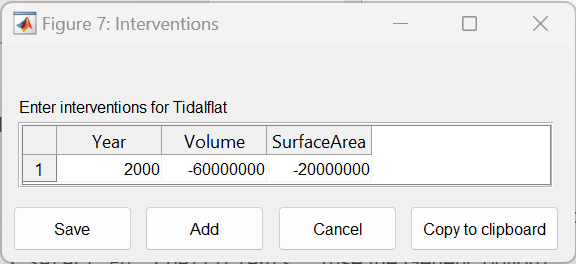

The defined interventions can be viewed on the Setting>Interventions tab. To include these in the model run:

`    Setup > Run Parameters > Conditions`        (set Include Interventions to 1)

Now re-run the model and give the new Case a name

### Analyse the Output

Whilst the Q-Plot tab provides a quick plot of the results for all water volumes and all sediment volumes, customised plots can be plotted using:

`    Analysis > Plots`

This allows different output variables and different Cases to be plotted on a single plot. For example:

openfig('Humber prism volumes.fig','visible');       %tidal prism variation for time around change

appinfo = struct with fields:
          id: 'AsmitaAPP'
        name: 'Asmita'
      status: 'updated'
    location: 'C:\Users\Ian\AppData\Roaming\MathWorks\MATLAB Add-Ons\Apps\Asmita'


It is easier to see the effect of the intervention if you set the amplitude of the cycles to zero using

        `Setup > Estuary > Water Levels       ` and set the cycles Amplitude to '0 0'

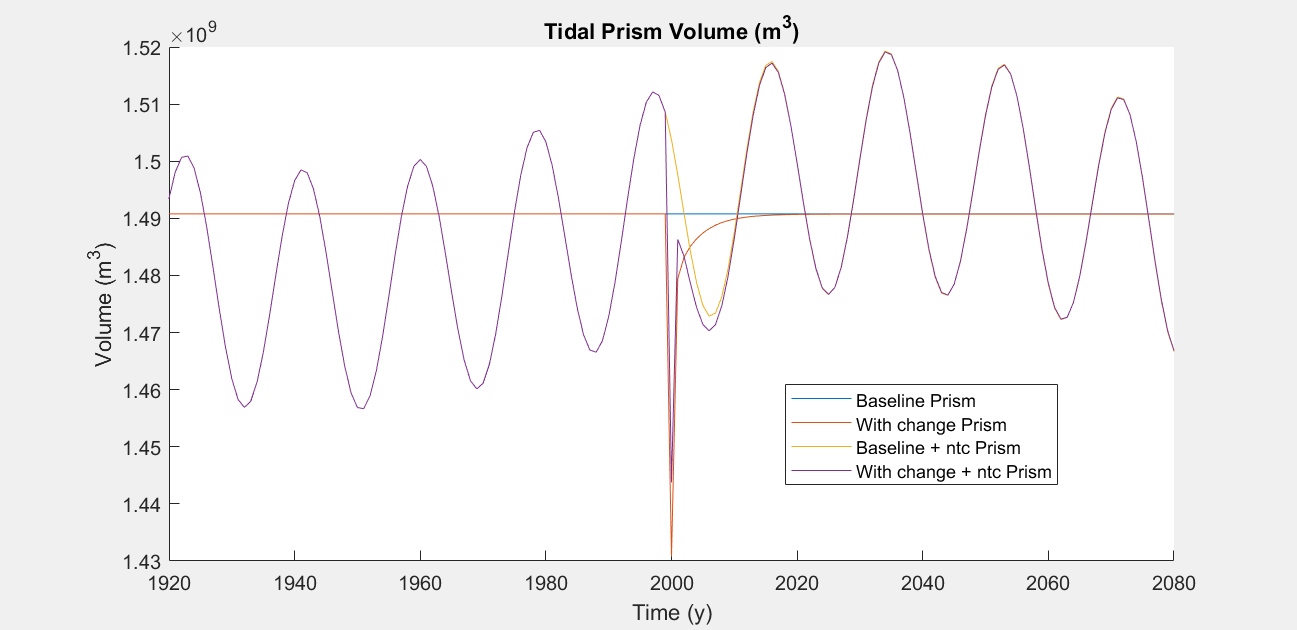

openfig('Humber flats volumes.fig','visible');       %impact of intervention on tidal flat

There are many other options available including an option to animate the changes over the duration of the model run.

If you plot the changes to the 3 elements you can see the interaction between the elements. Are the results what you would expect? 

Try changing the time step used in the model and running the case with the intervention:

        `Setup > Run Parameters > Time Step    ` (values of 0.5, 800, 2, 1700; or 0.1, 3200, 10, 1700)

Do the results remain the same in both cases? How would you interpret these additional results?

Explore varying other parameters, such as the global equilibrium concentration, vertical and horizontal exchanges, transport coefficient, etc to see how much these influence the result. 

If you look at the *Response* tab, you will see an estimate of the morphological timescale. With the parameters provided in the parameters spreadsheet, this is quite short at 6.4 years. For the Humber it is known to be more like ~40 years. Can you adjust the input parameters to increase the morphological timescale to be closer to 40 years? [NB: you do not need to re-run the model to check this. Just change the parameter settings and click on the *Response* tab. Once you have found some settings that are better calibrated you can re-run the model with the intervention and see what difference this has made].

## Conclusion

Hopefully that has provided you with a brief introduction to how to use Asmita. There are a lot of options and analysis tools available in the App. These are all explained in more detail in the CoastalTools manual. You can get to this from the Help menu option, the Matlab™ Search Documentation of using the following script:

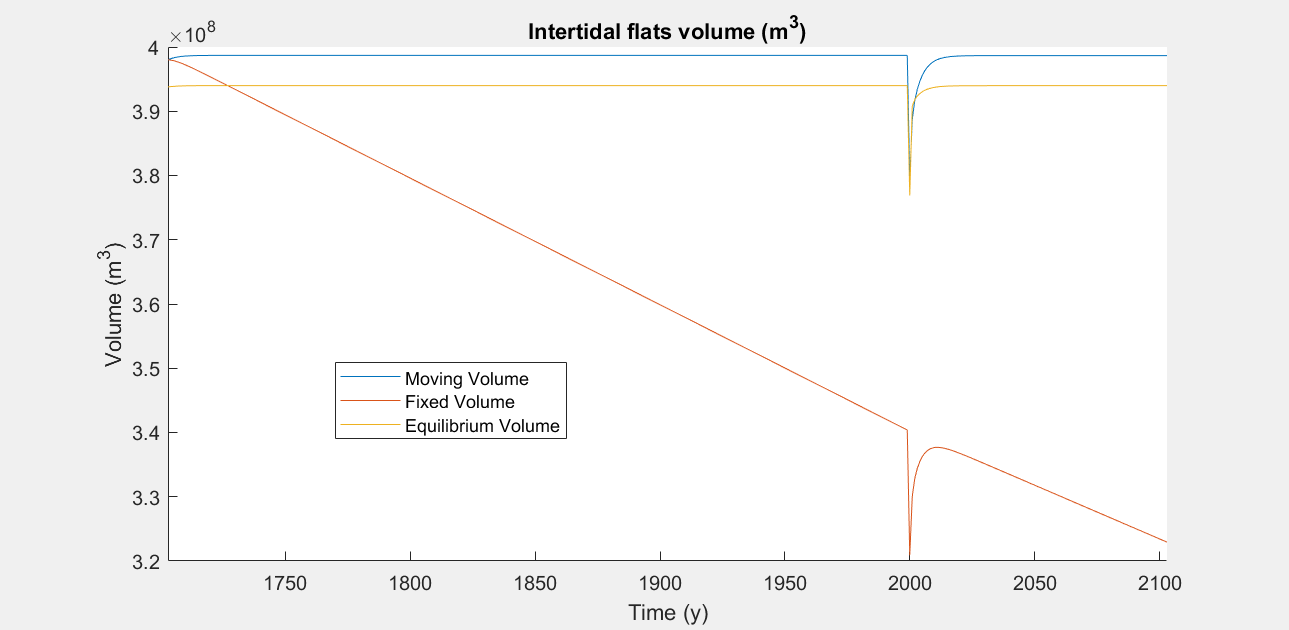

appinfo = matlab.apputil.getInstalledAppInfo;

idx = find(strcmp({appinfo.name},'CoastalTools'));
fpath = [appinfo(idx(1)).location,[filesep,'CoastalTools',filesep,'doc',...
                                        filesep,'CoastalTools manual.pdf']];
open(fpath)

## Bibliography

Kragtwijk, N.G., Stive, M.J.F., Wang, Z.B., Zitman, T.J., 2004. Morphological response of tidal basins to human interventions. Coastal Engineering, 51, 207-221. [https://doi.org/10.1016/j.coastaleng.2003.12.008](https://doi.org/10.1016/j.coastaleng.2003.12.008).

Rossington S K, Nicholls R J, Stive M J F and Wang Z B, 2011, Estuary schematisation in behaviour-oriented modelling. Marine Geology, 281 (1-4), 27-34, [https://doi.org/10.1016/j.margeo.2011.01.005.](https://doi.org/10.1016/j.margeo.2011.01.005.)

Stive, M.J.F., Capobianco, M., Wang, Z.B., Ruol, P., Buijsman, M.C., 1998. Morphodynamics of a tidal lagoon and adjacent coast. In: J. Dronkers, M.B.A.M. Scheffers (Eds.). Physics of Estuaries and Coastal Seas: 8th International Biennial Conference on Physics of Estuaries and Coastal Seas, 1996. A A Balkema, pp. 397-407.

Townend, 2017, [Art of Modelling](matlab:open('./The_art_of_modelling_v3.pdf')), ePaper, Course Notes, CoastalSEA, UK.

Townend, I.H., Wang, Z.B., Rees, J.G., 2007. Millennial to annual volume changes in the Humber Estuary. Proc.R.Soc.A, 463, 837-854. [https://doi.org/10.1098/rspa.2006.1798](https://doi.org/10.1098/rspa.2006.1798).

Townend, I.H., Wang, Z.B., Stive, M.J.E., Zhou, Z., 2016. Development and extension of an aggregated scale model: Part 1 – Background to ASMITA. China Ocean Engineering, 30(4), 482-504. [https://doi.org/10.1007/s13344-016-0030-x](https://doi.org/10.1007/s13344-016-0030-x).

Townend, I.H., Wang, Z.B., Stive, M.J.E., Zhou, Z., 2016. Development and extension of an aggregated scale model: Part 2 – Extensions to ASMITA. China Ocean Engineering, 30(5), 651-670. [https://doi.org/10.1007/s13344-016-0042-6](https://doi.org/10.1007/s13344-016-0042-6).

van Goor, M.A., Zitman, T.J., Wang, Z.B., Stive, M.J.F., 2003. Impact of sea-level rise on the morphological equilibrium state of tidal inlets. Marine Geology, 202, 211-227. [https://doi.org/10.1016/s0025-3227(03)00262-7](https://doi.org/10.1016/s0025-3227(03)00262-7).

Wang, Z.B., de Vriend, H.J., Stive, M.J.F., Townend, I.H., 2008. On the parameter setting of semi-empirical long-term morphological models for estuaries and tidal lagoons. In: C.M. Dohmen-Janssen, S.J.M.H. Hulscher (Eds.). River, Coastal and Estuarine Morphodynamics. Taylor & Francis, pp. 103-111. [https://doi.org/10.1201/noe0415453639-c14](https://doi.org/10.1201/noe0415453639-c14).